optimizacion de 

# Low-carbon operation strategy of virtual power plant considering

# progressive demand response

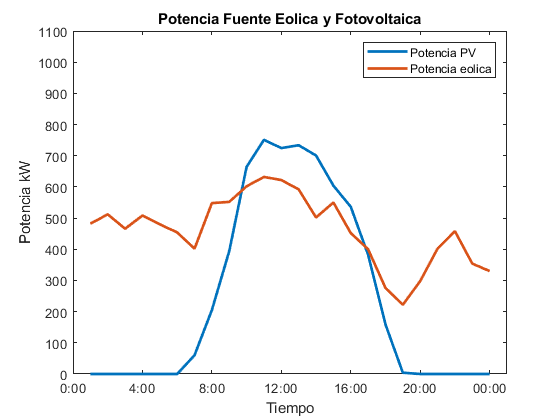







clear  
close all
clc
tiempo = linspace(1,24,24); % Vector de tiempo de 0 a 24 horas con 96 puntos (cada 15 minutos)


%%datos de los generadores
%wind=[250,206,233,194,200,187,111,174,276,301,316,311,296,251,275,226,200,138,111,149,201,229,177,165]*1.7;
irrad=[0,0,0,0,0,0,86,293,563,949,1073,1035,1048,1001,863,766,546,227,6,0,0,0,0,0]*0.7;
wind=[241,256,233,254,240,227,201,274,276,301,316,311,296,251,275,226,200,138,111,149,201,229,177,165]*2;
G_tg=[750 723 721 850 922 863 841 750 880 798 895 875 1023 1052 999 933 9550 859 789 942 923 953 956 891]*0.8;
plot(tiempo,irrad,'linewidth',2)
hold on
plot(tiempo,wind,'linewidth',2)
ylim([0 1100])
title('Potencia Fuente Eolica y Fotovoltaica')
xlabel('Tiempo')
ylabel('Potencia kW')
legend('Potencia PV','Potencia eolica')
xticks(0:4:24); % Establecer las marcas (ticks) cada 4 horas
% Crear etiquetas personalizadas para cada tick (4 horas)
xticklabels({'0:00', '4:00', '8:00', '12:00', '16:00', '20:00', '00:00'});
hold off





%%definimos el numero de periodos
T=24;
N_u=2;
Nload = 1;
%%parametros bateria 

SOC_0 = 0.4; % Estado de carga inicial 
SOC_min=0.2;
SOC_max= 0.95;

%%%%%%%%%%%%%%%%%%

%%%% parametros trubina de gas %%

a=[0.008 0.008];    %%Fuel cost factor a
b=[0.04  0.04] ;    %%Fuel cost factor b
c=[42  42];         %%Fuel cost facto c
C_Gs=[308 340];        %%star-up cost(yuan)  
C_Gt=[248 260];        %%shutdown cost(yuan)
PGi__max=[800 1000];       %%the upper limit of output(kW)
PGi__min=[300 500];        %%the lower limit of output(kW)
Pci=[400 500];       %%climbing power(kW)

lambda_Gi= 0.76; %% kg/kWh emision de carbono de referencia por unidad de electricidad


%%variblaes costos de operacion y mantenimiento de generadores eolico y
%%fotovoltaico
Swind= 0.52;
Ssol= 0.72;
Ssto= 0.5;

%%variable de precio de veenta y compra de electricidad de la red electrica
C_buy= [0.30 0.30 0.30 0.30 0.30 0.30 0.61 0.86 0.86 0.86 0.86 0.61 0.61 0.86 0.86 0.86 0.86 0.86 0.61 0.61 0.61 0.30 0.30 0.3];
C_sell=[0.26 0.26 0.26 0.26 0.26 0.26 0.50 0.68 0.68 0.68 0.68 0.50 0.50 0.68 0.68 0.68 0.68 0.68 0.50 0.50 0.50 0.26 0.26 0.26];

%%precio de incentivo en la respuesta a la demanda
p_e_sub = [0.25 0.25 0.25 0.25 0.25 0.25 0.25 0.25 0.53 0.95 0.95  0.53 0.53 0.53 0.53 0.53 0.95 0.95 0.95 0.95 0.95 0.25 0.25 0.25  ];

%%variables de decisión
P_w = wind';
P_sol = irrad';
P_G = sdpvar(T, N_u,'full'); % Potencia generada por unidades térmicas
P_buy = sdpvar(T,1);  % Potencia
P_sell= sdpvar(T,1);
Pload_DRi=[676,683,664,662,677,658,604,1204,1745,1937,2162,2027,1731,1633,2022,2220,2296,2349,2149,1728,967,743,632,600]*1.15; % Datos de carga para cada hora del día

Pload_DR = sum(Pload_DRi, 1); % Sumar sobre los usuarios para cada tiempo.
Pnet = sdpvar(T, 1); % Potencia intercambiada con la red
Pbat = sdpvar(T, 1); % Potencia de salida de la batería
Pcha = sdpvar(T, 1); % Potencia de carga de la batería en cada intervalo de tiempo
Pdis = sdpvar(T, 1); % Potencia de descarga de la batería en cada intervalo de tiempo
Ebat = sdpvar(T, 1); % Carga de la batería
%%variables Binarias 
%DR_reduction=sdpvar(T,Nload) % reduccion de la demanda 
%Demanda_modificada = sdpvar(T, 1);  % Variable de decisión para la demanda ajustada


delta_Gs = binvar(T,N_u);
delta_Gt = binvar(T,N_u);
delta_Gr = binvar(T,N_u); % Variables binarias para estado (encendido/apagado)

delta_bs = binvar(T, 1); % Variable booleana para compra/venta de electricidad
delta_cha = binvar(T, 1); % Variable booleana para cargar la batería
delta_dis = binvar(T, 1); % Variable booleana para descargar la batería
delta_sta = binvar(T, 1); % 1 si la batería está inactiva, 0 de lo contrario

%%variables para ev
N_EV = 50; % Número total de vehículos eléctricos
P_EV_charge = sdpvar(T, N_EV); % Potencia de carga para cada uno de los EVs
P_EV_discharge = sdpvar(T, N_EV); % Potencia de descarga para cada EV
SOC_EV = sdpvar(T, N_EV); % Estado de carga para cada vehículo

P_EV_max = 50; % Potencia máxima de carga/descarga de cada EV (kW)
delta_EV_charge = binvar(T, N_EV); % Variable binaria para carga de EVs
delta_EV_discharge = binvar(T, N_EV); % Variable binaria para descarga de EVs


%% costos operativos y de mantenimiento de los generadores fotovoltaico y eolico.
%% costos operativos de la turbina de gas
%% costos por compra y la venta de electricidad
%% costos por emision de carbono
%% costos de respuesta a la demanda


%% cada parte de la ecuacion tiene su equivalente
C_op = sum(Swind*P_w + Ssol*P_sol + Ssto * Pdis );
C_th = sum(sum(a(1)* P_G.^2 + b(1)* P_G + c(1) + delta_Gs* C_Gs(1) + delta_Gt*C_Gt(1)));
C_bs = sum(C_buy*P_buy + C_sell*P_sell);

% Emisiones de carbono y biomasa
beta_et_j = [0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305, 0.2250 0.2278, 0.2401, 0.2156, 0.2305];
EG_c = sum(sum(beta_et_j* P_G));
EG_b = sum(sum(lambda_Gi* P_G));
% Costo de emisiones
lambda_E=30; 
C_ce = lambda_E * EG_c - lambda_E * EG_b;

nu = 0.3 * ones(1, T); % Incentivo o penalización fija para cada intervalo de tiempo [1 x T]
lambda_Ei = 0.25 * ones(1, T); % Coeficiente de DR fijo para cada intervalo de tiempo [1 x T]
%Pload_DRi =  sdpvar(Nload,T);
%PloadDR=sdpvar(T,1)
C_DR = sum(sum(p_e_sub.* Pload_DR + nu./lambda_Ei));


% 
%Pesub=20*rand(T,Nload);
% 
% 
% % Definir parámetros de costos para la Respuesta a la Demanda
% Cost_DR = 10; % Costo por kW reducido mediante DR (puede ser un incentivo negativo)
% Incentivo_DR = 2; % Incentivo por cada kW reducido en respuesta a la demanda
% 
% % Costo total de DR (puede ser negativo si hay incentivos)
% %C_DR_new = sum(sum(Pesub .* DR_reduction)); % Ajustar el costo de acuerdo con la reducción
% C_DR_new = Cost_DR * sum(DR_reduction) - Incentivo_DR * sum(DR_reduction);

% C_EV_charge = C_buy * P_EV_charge; % Costo por cargar los EVs
% C_EV_discharge = -C_sell * P_EV_discharge; % Beneficio por vender energía desde los EVs


FminCvpp  =  C_ce   + C_th  +  C_bs + C_op  +  C_DR ; % C_DR_new; % +  ;


%C_EV_charge_total = sum(C_buy * sum(P_EV_charge, 2));
%C_EV_discharge_total = -sum(C_sell * sum(P_EV_discharge, 2));
%FminCvpp = FminCvpp + C_EV_charge_total + C_EV_discharge_total;

penalty_unbalanced_EV = 0.5; % Penalización para evitar descargas sin recarga
C_unbalanced = penalty_unbalanced_EV * sum(sum(P_EV_discharge - P_EV_charge));
FminCvpp = FminCvpp + C_unbalanced;
%%-213261

    Restricciones

constraints=[];


## Restricción de la turbina de gas.


% Restricciones para generadores térmicos
for t = 1:T
    for i = 1:N_u
        % Restricciones de potencia mínima y máxima con variables binarias
        constraints = [constraints, ...
            (delta_Gr(t, i) * PGi__min(i) <= P_G(t, i)) <= delta_Gr(t, i) * PGi__max(i)];
    end
end

%% Restricciones de rampa de potencia
for t = 1:T-1 % T-1 porque estamos considerando PGi(t+1)
    for i = 1:N_u
        % Restricción de cambio de potencia entre periodos consecutivos
        constraints = [constraints, ...
            -Pci(i) <= P_G(t+1, i) - P_G(t, i) <= Pci(i)];
    end
end

% Restricción de estado de generadores térmicos (no pueden estar encendidos y apagados simultáneamente)
for t = 1:T
    for i = 1:N_u
        constraints = [constraints, delta_Gs(t, i) + delta_Gt(t, i) <= 1];
    end
end

% Restricción de cambio de estado
delta_Gr_diff = sdpvar(T-1, N_u); % Diferencia de estado de encendido/apagado

% Calcular la diferencia de estado de encendido para cada generador y período
for t = 1:T-1
    for i = 1:N_u
        delta_Gr_diff(t, i) = delta_Gr(t+1, i) - delta_Gr(t, i);
    end
end

%% Restricción que asegura que el número total de cambios de estado no exceda el número de cambios posibles
sum_delta_Gdiff= sum(sum(delta_Gs - delta_Gt));

sum_delta_Gr_diff = sum(sum(delta_Gr_diff));



constraints = [constraints, sum_delta_Gr_diff <= sum_delta_Gdiff];

## **Restricciones de los EV**


%%%%SOC EV
SOC_min_EV = 0.2; % SOC mínimo de los EVs
SOC_max_EV = 0.9; % SOC máximo de los EVs
SOC_0_EV = 0.5; % SOC inicial de los EVs
E_EV_max = 200; % Capacidad máxima de los EVs (kWh)
eta_EV_charge = 0.95; % Eficiencia de carga
eta_EV_discharge = 0.9; % Eficiencia de descarga

for i = 1:N_EV
    % Restricciones para cada vehículo eléctrico
    constraints = [constraints, ...
        0 <= P_EV_charge(:, i) <= P_EV_max * delta_EV_charge(:, i), ...
        0 <= P_EV_discharge(:, i) <= P_EV_max * delta_EV_discharge(:, i), ...
        delta_EV_charge(:, i) + delta_EV_discharge(:, i) <= 1]; % No pueden cargarse y descargarse simultáneamente

    % Restricciones de SOC (estado de carga)
    constraints = [constraints, SOC_EV(1, i) == SOC_0_EV * E_EV_max];
    for t = 2:T
        constraints = [constraints, ...
            SOC_EV(t, i) == SOC_EV(t-1, i) + eta_EV_charge * P_EV_charge(t, i) - (1/eta_EV_discharge) * P_EV_discharge(t, i)];
    end
    constraints = [constraints, SOC_min_EV * E_EV_max <= SOC_EV(:, i) <= SOC_max_EV * E_EV_max];
end

## modelo de respuesta a la demanda

% % Máximo porcentaje de reducción de carga permitido
% max_DR_reduction = 0.10; % Máximo 20% de reducción por período
% % Añadir restricción para cada período y cada carga
% 
% 
%  % Restringir la cantidad de reducción de demanda para cada carga
% constraints = [constraints, DR_reduction <= max_DR_reduction * Pload_DRi'];
% 
% Demanda_base=[631,833,990,1071,1200,1250,1354,1594,1745,1937,2162,2027,1931,1933,2022,2220,2296,2349,2149,1728,967,743,632,600]*1; % Datos de carga para cada hora del día
% 
% % Variable de reducción de DR (se calcula como la diferencia entre demanda base y modificada)
% DR_reduction = Demanda_base' - Demanda_modificada; % DR_reduction será >= 0
% 
% % Definir la función de costo de Respuesta a la Demanda (C_DR_new)
% 
% % Restricción de que la demanda modificada no puede exceder la demanda base
% constraints = [constraints, Demanda_modificada <= Demanda_base']; % <= porque queremos reducir la demanda
% % La demanda modificada debe ser mayor o igual a un mínimo razonable (puede ser 0 o un valor específico)
% constraints = [constraints, Demanda_modificada >= 0.85 * Demanda_base']; % >= 50% de la demanda base como mínimo
% 
% 
% 
% constraints = [constraints, DR_reduction >= 0];  % No puede haber reducción negativa
% 
% %%carga total
% 
% Pload= sdpvar(T,1)
% constraints = [constraints, Pload == Demanda_base'-DR_reduction];  % No puede haber reducción negativa


## restricciones de balance de potencia



% Añadir la restricción de balance de potencia para cada período de tiempo
Pload=[825,900,1190,1171,1300,1250,1354,1204,1745,1937,2162,2027,1731,1633,2022,2220,2296,2349,2149,1728,967,743,632,600]*1; % Datos de carga para cada hora del día

for t = 1:T
    constraints = [constraints, ...
        Pnet(t) + wind(t) + irrad(t) + sum(P_G(t, :)) + Pbat(t) + P_EV_discharge(t)- P_EV_charge(t)  == Pload(t)];
end
        %Pnet(t) + wind(t) + irrad(t) + sum(P_G(t, :))   == Demanda_base(t) - (DR_reduction(t, :)) + Pbat(t)  ];


## restricciones de compra y venta de electricidad de la VPP


Ppower = 200;           % Límite de potencia de intercambio

% Límite de Pnet
constraints = [constraints, -Ppower <= Pnet <= Ppower];
% Límite de Psell
constraints = [constraints, -Ppower <= P_sell <= 0];
% Límite de Pbuy
constraints = [constraints, 0 <= P_buy <= Ppower];


constraints= [constraints,[implies(Pnet>=0, Pnet==P_buy),implies(delta_bs==1,Pnet==P_buy)]];
constraints= [constraints,[implies(Pnet<=0, Pnet==P_sell),implies(delta_bs==0,Pnet==P_sell)]];




## restricciones de las baterias

Pcs=300;


    % Restricciones de carga y descarga
    constraints = [constraints,... 
        -Pcs <= Pbat <= Pcs ,...
        Pbat(t) == Pcha(t) - Pdis(t), ... % Definición de la salida de la batería
        0 <= Pcha <= Pcs , ... % Límite de carga controlado por delta_cha
        0 >= Pdis >= -Pcs , ... % Límite de descarga controlado por delta_dis
         
        delta_cha + delta_dis + delta_sta == 1,...%, ... % Una sola operación a la vez
           Pbat + Pdis + Pcha  == 0]; % Condición de estado inactivo
     
 constraints= [constraints,[implies(Pbat>=0, Pbat==Pcha),implies(delta_cha==1,Pbat==Pcha)]];
 constraints= [constraints,[implies(Pbat<=0, Pbat==Pdis),implies(delta_dis==1,Pbat==Pdis)]];
         


## estados del SOC de la bateria

Emax = 1000; % Capacidad máxima de la batería en kWh
eta_cha = 0.95; % Eficiencia de carga
eta_dis = 0.95; % Eficiencia de descarga
% Inicialización de la carga de la batería
SOC=sdpvar(T,1);

constraints = [constraints,Ebat(1) == SOC_0 * Emax]; % Estado de carga inicial

% Restricción dinámica de carga de la batería
for t = 2:T
    constraints = [constraints, Ebat(t) == Ebat(t-1) + Pcha(t) - Pdis(t)];
end

% Restricción de energía disponible
constraints = [constraints, ...
    Emax * (SOC_min - SOC_0) <= sum(Pcha* eta_cha - Pdis* eta_dis) <= Emax * (SOC_max - SOC_0)];

% Restricción de carga y descarga nula
constraints = [constraints, sum(Pcha + Pdis) == 0];
SOC=Ebat/Emax;

##  Restricción de incentivos DR.

Fmin = 0.1; % Valor mínimo de fluctuación
Fmax = 0.8; % Valor máximo de fluctuación
chi = 0.5; % Valor máximo del coeficiente de respuesta a la demanda

% Variables de decisión
lambda_x = sdpvar(T, 1); % Coeficiente de respuesta a la demanda
W_DR = 1; % Factor de ponderación para cada usuario
Pload_i =[0.5, 0.4, 0.4, 0.3, 0.3, 0.6, 1.2, 1.5, 1.0, 0.8, 0.7, 0.6, ...
                    0.5, 0.5, 0.4, 0.6, 0.7, 1.2, 1.8, 2.0, 1.5, 1.0, 0.8, 0.6]; % kWh

% Coeficientes de respuesta a la demanda
lambda_min_x = 0.2; % Ejemplo de valor mínimo
lambda_max_x = 0.5; % Ejemplo de valor máximo

% Restricción de fluctuación
F_x = (lambda_max_x - lambda_min_x) / lambda_max_x;
constraints = [constraints, Fmin <= F_x, F_x <= Fmax];

% Restricción de capacidad de respuesta
%constraints = [constraints, (sum(lambda_min_x * W_DR * Pload_i) <= lambda_x )<= sum(lambda_max_x * W_DR * Pload_i)];


% Restricción del coeficiente de respuesta
constraints = [constraints, (0 <= lambda_x) <= chi];
% optimize(constraints)

## Resolver el problema

options = sdpsettings('verbose', 2, 'solver', 'Cplex'); 
sol = optimize(constraints,FminCvpp,options);

CPXPARAM_Simplex_Display                         2
CPXPARAM_Barrier_Display                         2
Tried aggregator 2 times.
MIQP Presolve eliminated 5817 rows and 617 columns.
MIQP Presolve modified 680 coefficients.
Aggregator did 1248 substitutions.
Reduced MIQP has 3888 rows, 4911 columns, and 10426 nonzeros.
Reduced MIQP has 1268 binaries, 1 generals, 0 SOSs, and 0 indicators.
Reduced MIQP objective Q matrix has 48 nonzeros.
Presolve time = 0.02 sec. (14.38 ticks)
Probing fixed 2 vars, tightened 2 bounds.
Probing time = 0.00 sec. (0.48 ticks)
Tried aggregator 1 time.
MIQP Presolve eliminated 4 rows and 2 columns.
Reduced MIQP has 3884 rows, 4909 columns, and 10418 nonzeros.
Reduced MIQP has 1266 binaries, 1 generals, 0 SOSs, and 0 indicators.
Reduced MIQP objective Q matrix has 48 nonzeros.
Presolve time = 0.00 sec. (4.45 ticks)
Probing time = 0.00 sec. (0.39 ticks)
Clique table members: 33.
MIP emphasis: balance optimality and feasibility.
MIP search method: dynamic search.
Pa

if sol.problem == 0
    % Si no hay errores
    fprintf('Optimización completada con éxito.\n');
    P_G_opt = value(P_G);
    P_w_opt = value(P_w);
    P_sol_opt = value(P_sol);
    
else
    disp('Problema en la optimización:');
    disp(yalmiperror(sol.problem));
end

Optimización completada con éxito.


## valores


% Obtén los valores de las variables de decisión
P_w_val = value(P_w);
P_sol_val = value(P_sol);
P_G_val = value(P_G);
P_buy_val = value(P_buy);
P_sell_val = value(P_sell);
Pload_DRi_val = value(Pload_DRi);
Pload_DR_val = value(Pload_DR);
Pnet_val = value(Pnet);
Pbat_val = value(Pbat);
Pcha_val = value(Pcha);
Pdis_val = value(Pdis);
Ebat_val = value(Ebat);





% Muestra los valores
disp('Valores de las variables de decisión:');

Valores de las variables de decisión:


disp('P_w:');

P_w:


disp(P_w_val);

   482
   512
   466
   508
   480
   454
   402
   548
   552
   602
   632
   622
   592
   502
   550
   452
   400
   276
   222
   298
   402
   458
   354
   330



disp('P_sol:');

P_sol:


disp(P_sol_val);

         0
         0
         0
         0
         0
         0
   60.2000
  205.1000
  394.1000
  664.3000
  751.1000
  724.5000
  733.6000
  700.7000
  604.1000
  536.2000
  382.2000
  158.9000
    4.2000
         0
         0
         0
         0
         0



disp('P_G:');

P_G:


disp(P_G_val);

   1.0e+03 *

    0.5930         0
    0.5380         0
    0.4740    0.5000
    0.4130    0.5000
    0.4909    0.5000
    0.4856    0.5000
    0.5209    0.5209
    0.3125    0.5000
    0.4562    0.5000
    0.4207    0.5000
    0.5131    0.5131
    0.4305    0.5000
    0.5554         0
    0.3000    0.5000
    0.5382    0.5382
    0.7159    0.7159
    0.8000    0.8878
    0.8000    1.0000
    0.8000    0.9903
    0.7732    0.8568
    0.3732    0.5000
    0.4828         0
    0.5280         0
    0.5200         0



disp('P_buy:');

P_buy:


disp(P_buy_val);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



disp('P_sell:');

P_sell:


disp(P_sell_val);

 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000



disp('Pload_DRi:');

Pload_DRi:


disp(Pload_DRi_val);

   1.0e+03 *

  Columns 1 through 17

    0.7774    0.7854    0.7636    0.7613    0.7785    0.7567    0.6946    1.3846    2.0067    2.2275    2.4863    2.3310    1.9906    1.8779    2.3253    2.5530    2.6404

  Columns 18 through 24

    2.7013    2.4713    1.9872    1.1120    0.8544    0.7268    0.6900



disp('Pload_DR:');

Pload_DR:


disp(Pload_DR_val);

   1.0e+03 *

  Columns 1 through 17

    0.7774    0.7854    0.7636    0.7613    0.7785    0.7567    0.6946    1.3846    2.0067    2.2275    2.4863    2.3310    1.9906    1.8779    2.3253    2.5530    2.6404

  Columns 18 through 24

    2.7013    2.4713    1.9872    1.1120    0.8544    0.7268    0.6900



disp('Pnet:');

Pnet:


disp(Pnet_val);

 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
   57.1138
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000
 -200.0000



disp('Pbat:');

Pbat:


disp(Pbat_val);

         0
         0
         0
         0
         0
         0
         0
 -111.5740
         0
         0
         0
         0
         0
 -119.7000
         0
         0
         0
    6.9862
  282.4875
         0
  -58.1997
         0
         0
         0



disp('Pcha:');

Pcha:


disp(Pcha_val);

         0
         0
         0
         0
         0
         0
         0
  111.5740
         0
         0
         0
         0
         0
  119.7000
         0
         0
         0
         0
         0
         0
   58.1997
         0
         0
         0



disp('Pdis:');

Pdis:


disp(Pdis_val);

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   -6.9862
 -282.4875
         0
         0
         0
         0
         0



disp('Ebat:');

Ebat:


disp(Ebat_val);

  400.0000
  400.0000
  400.0000
  400.0000
  400.0000
  400.0000
  400.0000
  511.5740
  511.5740
  511.5740
  511.5740
  511.5740
  511.5740
  631.2740
  631.2740
  631.2740
  631.2740
  638.2602
  920.7477
  920.7477
  978.9474
  978.9474
  978.9474
  978.9474



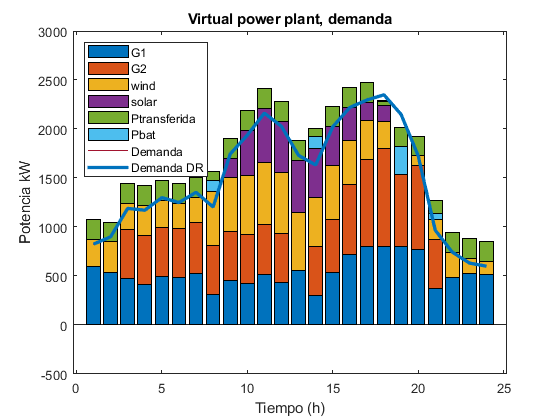






datos=[P_G_val(:,1),P_G_val(:,2), P_w_val, P_sol_val,Pnet_val,-Pbat_val]; %, -Pbat_val]
bar(datos,'stacked','FaceColor','flat' )
ylim([-500,3000])
title('Virtual power plant, demanda');
xlabel('Tiempo (h)');
ylabel('Potencia kW');
hold on
plot(Pload)
plot(value(Pload),'LineWidth',2.5)
legend({'G1', 'G2 ','wind', 'solar','Ptransferida','Pbat','Demanda','Demanda DR' }, 'Location', 'northwest'); % Leyenda

hold off


figure
datos1=[P_G_val(:,1),P_G_val(:,2),P_w_val, P_sol_val,Pbat_val]%,Pbat_val];  %, -Pbat_val]

datos1 = 	1.0e+03 *

    0.5930         0    0.4820         0         0
    0.5380         0    0.5120         0         0
    0.4740    0.5000    0.4660         0         0
    0.4130    0.5000    0.5080         0         0
    0.4909    0.5000    0.4800         0         0
    0.4856    0.5000    0.4540         0         0
    0.5209    0.5209    0.4020    0.0602         0
    0.3125    0.5000    0.5480    0.2051   -0.1116
    0.4562    0.5000    0.5520    0.3941         0
    0.4207    0.5000    0.6020    0.6643         0


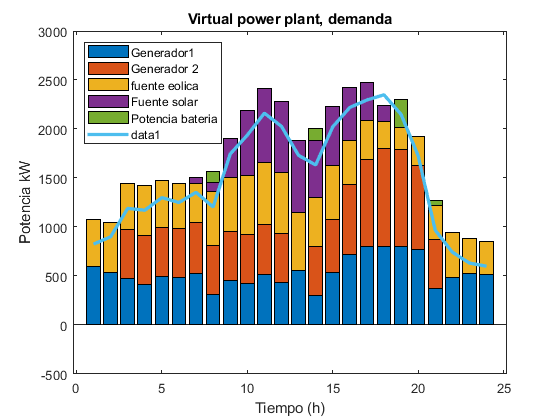

bar(datos1,'stacked','FaceColor','flat')
ylim([-500,3000])
title('Virtual power plant, demanda');
xlabel('Tiempo (h)');
ylabel('Potencia kW');
legend({'Generador1', 'Generador 2 ','fuente eolica', 'Fuente solar','Potencia bateria' }, 'Location', 'northwest'); % Leyenda
hold on
plot(value(Pload),'LineWidth',2.5)

hold off

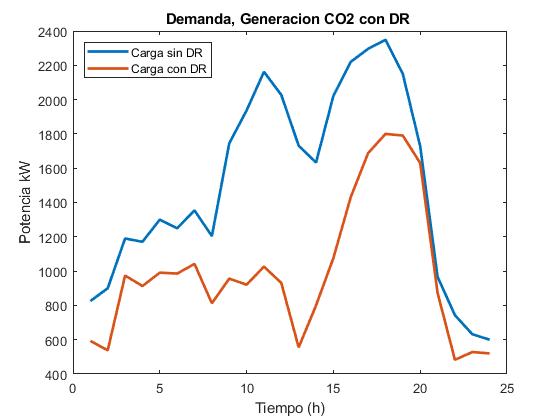


figure
plot(value(Pload),'LineWidth',2)
xlabel('Tiempo (h)');
ylabel('Potencia kW');
title('Demanda, Generacion CO2 con DR ');

hold on 
plot(P_G_val(:,1)+P_G_val(:,2),'LineWidth',2)
legend({'Carga sin DR', 'Carga con DR '}, 'Location', 'northwest'); % Leyenda
hold off

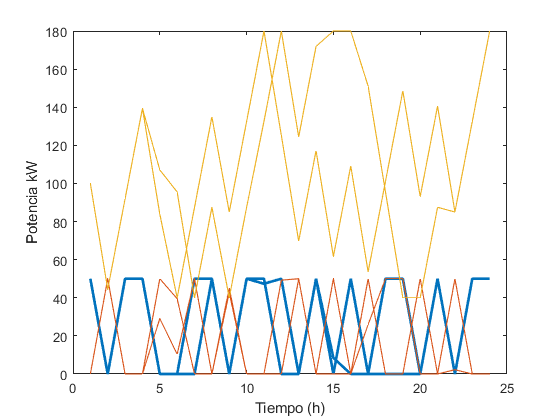


datos2 = P_G_val(:,1)+P_G_val(:,2)+ P_w_val+P_sol_val +Pnet_val-Pdis_val;
figure

plot(value(P_EV_charge),'LineWidth',2)
hold on
plot(value( P_EV_discharge)) 
plot(value( SOC_EV))
hold off
xlabel('Tiempo (h)');
ylabel('Potencia kW');

%legend({'Carga sin DR', 'Carga con DR '}, 'Location', 'northwest'); % Leyenda

%plot(value(DR_reduction),'LineWidth',2)